# Pressure sensor placement for leakage detection

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## Water Network

d=epanet('Hanoi.inp');

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "Hanoi.inp"...
Input File "Hanoi.inp" loaded successfully.


nj = double(d.getNodeJunctionCount);
nn = double(d.getNodeCount);
reservInd = d.getNodeReservoirIndex;

## Calculate Sensitivity matrix

*[1] *Cugueró , M., Puig, V., Quevedo, J. Optimal pressure sensor placement and assessment f*or leak location using a relaxed isolation index: Application to the Barcelona water network, Control Eng. Pract., vol. 63, pp. 1-12, Jun. 2017.*

Calculate healthy states in extended time simulation:

d.setTimeSimulationDuration(24*60*60) % greater weight to low demand hours
d.setTimePatternStart(0) %in seconds
allParameters=d.getComputedTimeSeries;
P0 = allParameters.Pressure';
P0(d.getNodeReservoirIndex,:)=[];
Dem0 = allParameters.Demand';
simSteps = size(P0,2);
% Create Augmented-time Sensitivity Matrix
% Simulate all leakages and get all scenarios pressures

leak_mag_desir=mean(mean(Dem0(Dem0>0)));
mean_pressure = mean(mean(P0(P0>0)));
leak_emit = leak_mag_desir/sqrt(mean_pressure);
emit0=d.getNodeEmitterCoeff;
S = zeros(nj,nj);
for leak=1:nj
    clc
    disp('Calculating Sensitivity Matrix...')
    disp(['Simulating leakage ',num2str(leak),' out of ',num2str(nj)])
    emit=zeros(size(emit0));
    emit(leak)=leak_emit; % set emitter coefficient (leakage) value
    d.setNodeEmitterCoeff(emit);
    allParameters=d.getComputedTimeSeries;
    P = allParameters.Pressure';
    P(d.getNodeReservoirIndex,:)=[];
    Dem = allParameters.Demand';
    leak_mag = Dem(leak,:)-Dem0(leak,:);
    Stmp=(P-P0)./(leak_mag);
    rmax = max(abs(Stmp),[],1);
    Stmp = abs(Stmp)./rmax;
    S(:,leak) = max(Stmp')'; % --> main difference in max-min Sensitivity!!!
end

Calculating Sensitivity Matrix...


Simulating leakage 1 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 2 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 3 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 4 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 5 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 6 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 7 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 8 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 9 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 10 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 11 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 12 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 13 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 14 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 15 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 16 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 17 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 18 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 19 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 20 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 21 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 22 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 23 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 24 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 25 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 26 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 27 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 28 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 29 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 30 out of 31


Calculating Sensitivity Matrix...


Simulating leakage 31 out of 31


## Place sensors using GA

Select number of sensors to be installed:

sensors_num=4;

Define existing sensors in the network:

exist_sens_ind=[]; % define existing sensors in the network
% exist_sens_ind=d.getNodeIndex({'14','63','114','399','572','302','662'});

Solve using GA: Maximize the minimum sensitivity of all sensors to any leakage

[res,fvalSenTr] = SolveEnum2GA(S,nj,sensors_num,exist_sens_ind)

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


res =      0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0


fvalSenTr = 0.4507

Find calculated sensor node index and IDs:

% u=res;
% Sm = S(u>0,:);
% Smax = max(Sm);
% cost(1) = min(Smax);
% cost(2) = mean(Smax);
% sensors = length(find(u>0.1));
% sens_ind = find(u>0.1);
% sens_IDs = d.getNodeNameID(sens_ind);
% save('SensorIDs_Hanoi','sens_IDs','cost')
load SensorIDs_Hanoi.mat % load optimal solution (for demonstration only!)
sens_ind = d.getNodeIndex(sens_IDs)

sens_ind =     12    15    21    29


% Display solution

## Plot sensors:

d.plot

ans =   Axes with properties:

             XLim: [2.2617e+03 7.7149e+03]
             YLim: [4.0385e+03 9.4077e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


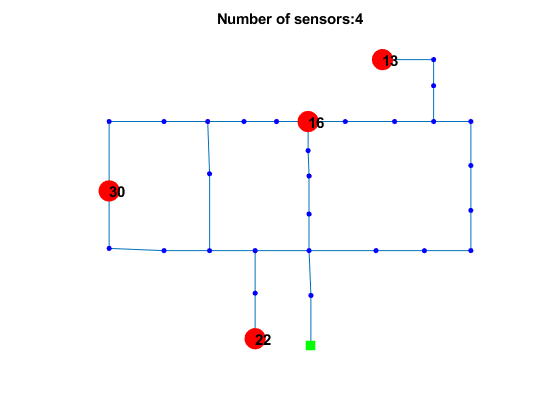

legend('off')
coor=d.getNodeCoordinates;
x=coor{1}(sens_ind);y=coor{2}(sens_ind);
plot(x,y,'o','LineWidth',2,'MarkerEdgeColor','r','MarkerFaceColor','r','MarkerSize',14)
fontweight='bold';
fontsize=11;
for i=1:length(sens_ind)
    text(x(i)-5,y(i),d.getNodeNameID{sens_ind(i)},'Color','black','FontWeight',fontweight,'Fontsize',fontsize)
end
title(['Number of sensors:',num2str(sensors_num)])

Unload toolkit

d.unload

EPANET Class is unloaded


## Cost function

function [res,fval] = SolveEnum2GA(S,nj,sensors,exist_sens_ind)

Initialize parameters

u = ones(1,nj);
lb = zeros(size(u));
ub = ones(size(u));

Existing sensors:

if ~isempty(exist_sens_ind)
    Aes = zeros(1,nj);
    Aes(exist_sens_ind) = 1;
    bes = length(exist_sens_ind);
else
    Aes=[];
    bes=[];
end

GA options

options = gaoptimset(@ga);
% options.MutationFcn = @mutationgaussian; % select mutation function
options.PlotFcn = @gaplotbestf; % plot the fitness function
options.PopulationSize = 200; % population in each generation
% options.Generations=1; % set maximum generations
options.StallGenLimit=5; % generation stall limit
options.UseParallel=0; % parallel simulation
% options.InitialPopulation=u;

## Enumeration loops for threshold and sensors

sen_num_l = sensors(1);
if length(sensors)==1
    sen_num_u = sensors(1);
else
    sen_num_u = sensors(2);
end

GA Problem struct

problem = struct(...
'fitnessfcn',@(u)GACostFunction(u,S),... %Fitness function
'nvars',nj,... %Number of design variables
'Aineq',[ones(1,nj); -ones(1,nj); Aes; -Aes],... % contraint on number of sensors
'bineq',[sen_num_u; -sen_num_l; bes; -bes ],...
'Aeq',[],...
'beq',[],...
'lb',lb,...
'ub',ub,...
'nonlcon',[],... %Nonlinear constraint function
'intcon',[1:nj],... %Index vector for integer variables
'options',options,...%Options created with gaoptimset
'rngstate',[]); %state of the random number generator

Solve GA

% GACostFunction(u,S)
[res,fval] = ga(problem);
end

Cost function: min sensitivity of all leaks

function cost = GACostFunction(u,S)
Sm = S(u>0,:);
Smax = max(Sm);
% cost = 1-min(Smax);        
% cost = 1-mean(Smax);         
cost = 1-min(Smax)-0.1*mean(Smax);
end